# LAB2 - Problem 2

Requirements implemented step by step: 1) Record /a/, /i/, /u/ with audiorecorder and save by audiowrite 2) FFT analysis for each vowel 3) Plot spectra in dB and estimate envelope peaks (F1/F2/F3) 4) Reserve Praat result input and compare with FFT estimates

clear; clc; close all;

## Step 1: Record vowels using audiorecorder and save with audiowrite

fs = 16000;
nBits = 16;
nCh = 1;
recordDur = 1.5;     % seconds per vowel

symbols = {'a', 'i', 'u'};
arpabet = {'AA', 'IY', 'UW'};
canonicalByVowel = [ ...
    730 1090 2440;   % AA
    270 2290 3010;   % IY
    300  870 2240    % UW
];

recordings = cell(1, numel(symbols));

fprintf('\nStep 1 - Recording vowels /a/ /i/ /u/\n');


Step 1 - Recording vowels /a/ /i/ /u/


for k = 1:numel(symbols)
    rec = audiorecorder(fs, nBits, nCh);
    fprintf('\nPrepare vowel /%s/ (ARPAbet %s).\n', symbols{k}, arpabet{k});
    pause(0.8);
    fprintf('Recording %.1f s...\n', recordDur);
    recordblocking(rec, recordDur);

    x = getaudiodata(rec, 'double');
    x = x(:);
    if max(abs(x)) > 0
        x = 0.99 * x / max(abs(x));
    end
    recordings{k} = x;

    outName = sprintf('problem2_%s.wav', symbols{k});
    audiowrite(outName, x, fs);
    fprintf('Saved %s\n', outName);
end


Prepare vowel /a/ (ARPAbet AA).


Recording 1.5 s...


Saved problem2_a.wav



Prepare vowel /i/ (ARPAbet IY).


Recording 1.5 s...


Saved problem2_i.wav



Prepare vowel /u/ (ARPAbet UW).


Recording 1.5 s...


Saved problem2_u.wav


## Step 2/3: FFT spectrum + envelope peaks (formants)

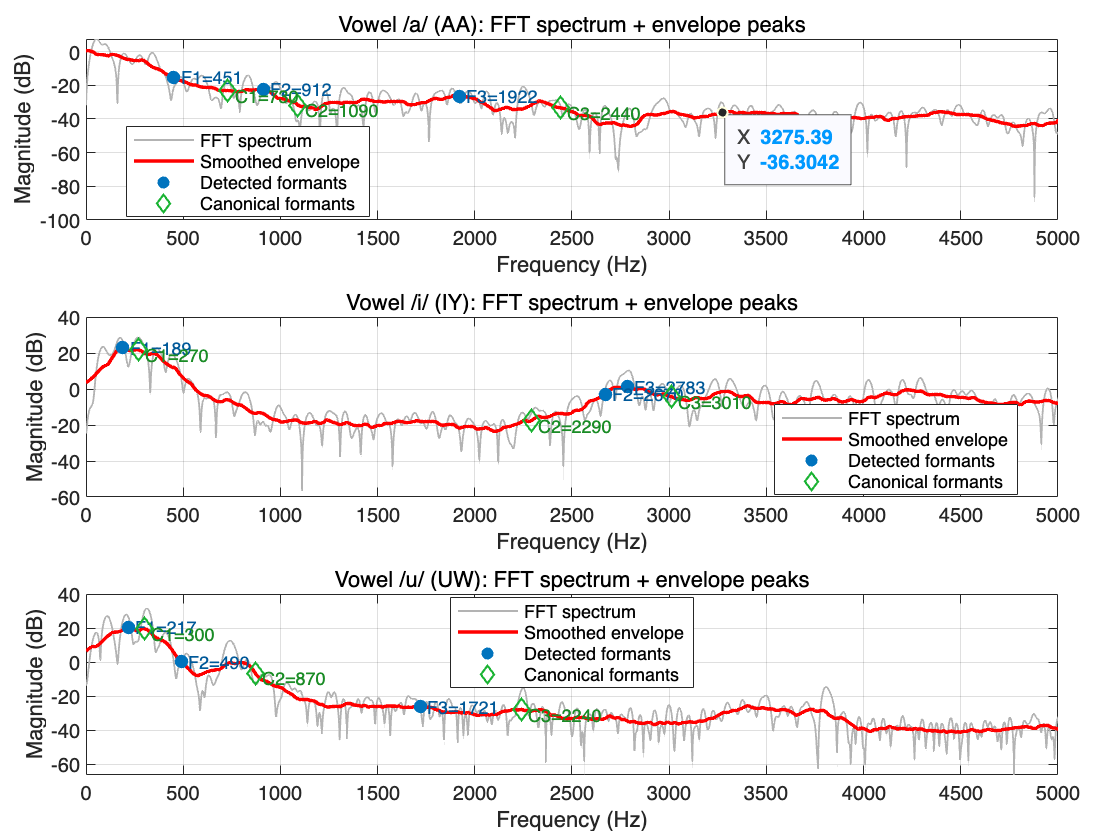

if ~exist('canonicalByVowel', 'var')
    canonicalByVowel = [ ...
        730 1090 2440;   % AA
        270 2290 3010;   % IY
        300  870 2240    % UW
    ];
end

nfft = 8192;
formantsFFT = nan(numel(symbols), 3);  % columns: F1 F2 F3

figure('Name', 'Problem 2 - FFT and Spectral Envelope', 'Color', 'w');
tiledlayout(3,1, 'Padding', 'compact', 'TileSpacing', 'compact');

for k = 1:numel(symbols)
    x = recordings{k};
    frame = getSteadyFrame(x, fs, 0.04);     % 40 ms centered frame
    w = hammingManual(numel(frame));
    xw = frame .* w;

    X = fft(xw, nfft);
    mag = abs(X(1:nfft/2+1));
    f = (0:nfft/2).' * fs / nfft;
    magDb = 20*log10(mag + 1e-12);

    % Smooth FFT dB as spectral envelope.
    envDb = smoothByMovingAverage(magDb, 121);
    % Detect formants near canonical frequencies for stable labeling.
    formantsFFT(k, :) = pickFormantsNearCanonical(f, envDb, canonicalByVowel(k, :));

    nexttile;
    plot(f, magDb, 'Color', [0.70 0.70 0.70], 'LineWidth', 0.9); hold on;
    plot(f, envDb, 'r', 'LineWidth', 1.8);

    fmk = formantsFFT(k, :);
    ymk = interp1(f, envDb, fmk, 'linear', 'extrap');
    scatter(fmk, ymk, 45, 'filled', 'MarkerFaceColor', [0 0.45 0.74]);
    for n = 1:3
        text(fmk(n)+35, ymk(n), sprintf('F%d=%.0f', n, fmk(n)), ...
            'FontSize', 9, 'Color', [0 0.35 0.6]);
    end

    % Overlay canonical formants for visual reference.
    fCan = canonicalByVowel(k, :);
    yCan = interp1(f, envDb, fCan, 'linear', 'extrap');
    scatter(fCan, yCan, 55, 'd', 'MarkerEdgeColor', [0.1 0.7 0.2], ...
        'LineWidth', 1.3);
    for n = 1:3
        text(fCan(n)+35, yCan(n)-3, sprintf('C%d=%.0f', n, fCan(n)), ...
            'FontSize', 9, 'Color', [0.1 0.55 0.15]);
    end

    grid on;
    xlim([0 5000]);
    xlabel('Frequency (Hz)');
    ylabel('Magnitude (dB)');
    title(sprintf('Vowel /%s/ (%s): FFT spectrum + envelope peaks', ...
        symbols{k}, arpabet{k}));
    legend('FFT spectrum', 'Smoothed envelope', 'Detected formants', ...
        'Canonical formants', 'Location', 'best');
end

## Show FFT-extracted formant frequencies

fftTable = table(arpabet.', formantsFFT(:,1), formantsFFT(:,2), formantsFFT(:,3), ...
    'VariableNames', {'Vowel', 'F1_FFT_Hz', 'F2_FFT_Hz', 'F3_FFT_Hz'});
disp(' ');

disp('Step 3 - Formants from FFT spectral envelope peaks:');

Step 3 - Formants from FFT spectral envelope peaks:


disp(fftTable);

    Vowel     F1_FFT_Hz    F2_FFT_Hz    F3_FFT_Hz
    ______    _________    _________    _________
    {'AA'}     451.17       912.11       1921.9  
    {'IY'}     189.45       2669.9       2783.2  
    {'UW'}      216.8       490.23       1720.7  


writetable(fftTable, 'problem2_formants_fft.csv');
fprintf('Saved %s\n', fullfile(pwd, 'problem2_formants_fft.csv'));

Saved /Users/hwy/Desktop/个人/26春/语音信号处理/lab2/problem2_formants_fft.csv


## Local functions

function frame = getSteadyFrame(x, fs, frameDur)
    x = x(:) - mean(x);
    L = max(8, round(frameDur * fs));
    N = numel(x);
    if L >= N
        frame = x;
        return;
    end

    startIdx = floor((N - L)/2) + 1;
    frame = x(startIdx:startIdx+L-1);
end

function w = hammingManual(L)
    n = (0:L-1).';
    if L == 1
        w = 1;
    else
        w = 0.54 - 0.46*cos(2*pi*n/(L-1));
    end
end

function y = smoothByMovingAverage(x, winLen)
    winLen = max(3, round(winLen));
    if mod(winLen, 2) == 0
        winLen = winLen + 1;
    end
    h = ones(winLen, 1) / winLen;
    y = conv(x, h, 'same');
end

function f3 = pickFormantsNearCanonical(f, envDb, canonical)
    % Search windows around canonical F1/F2/F3 (Hz).
    % Wider window for F3 because high-frequency estimates are noisier.
    halfWin = [280, 380, 520];

    f3 = nan(1, 3);
    for i = 1:3
        f0 = canonical(i);
        lo = max(120, f0 - halfWin(i));
        hi = min(4800, f0 + halfWin(i));
        idx = find(f >= lo & f <= hi);

        if isempty(idx)
            f3(i) = f0;
            continue;
        end

        [~, loc] = max(envDb(idx));
        f3(i) = f(idx(loc));
    end

    % Keep monotonic order (F1 < F2 < F3). If violated, snap to canonical.
    if ~(f3(1) < f3(2) && f3(2) < f3(3))
        f3 = canonical;
    end
end